clc, clear, close all

%%%ПАРАМЕТРЫ СИСТЕМЫ:
numSymPerFrame = 2^12;  % Кол-во бит 
M = 16;                 % Глубина модуляции
k = log2(M);
filtlen = numSymPerFrame*2^(0);         % Длина фильтра в символах
rolloff = 0.25;         % Коэффициент сглаживания
sps = 32;               % количества выборок на символ
fss = 0.2 * sps;       % Для управления смещением спм сигнала от 0 до 2pi
EbNoVec = (0:5);       % величина Eb/No (dB)
codeRate = 2/3;         % для кода со скоростью 2/3 с помощью функции poly2trellis. 
traceBack = 20;         % глубина обратного прослеживания для декодера Витерби [бит]. Обычно выбирается 5-10*ограничение кода (=2 из 2/3)

%%ОСШ
snr = EbNoVec + 10*log10((k*codeRate)/sps); %k = BitsPerSymbol; sps = SamplesPerSymbol

        berEst = zeros(size(EbNoVec));
        for n = 1:length(snr)
            % Обнуление ошибок и бит
            numErrs = 0;
            numBits = 0;
        
            while numErrs < 10 || numBits < 1e3

%ГЕНЕРАЦИЯ ВХОДНЫХ ДАННЫХ
        
        dataIn = randi([0 1],numSymPerFrame,1);

%%ПРИМЕНЕНИЕ СВЕРТОЧНОГО КОДА:

            constrlen = [5 4];           % Длина кодового ограничения
            genpoly = [23 35 0; 0 5 13]; % Создание Полиномов
    
            tPoly = poly2trellis(constrlen,genpoly); %Определение решетки сверточного кодирования                                         
        
%%КОДИРОВАНИЕ ВХОДНЫХ ДАННЫХ:

            %dataEnc = convenc(dataIn,tPoly);
            dataSym = bit2int(dataIn,k);
         
%%КАМ 
            txSig = qammod(dataSym,M);


%%СОЗДАНИЕ ФИЛЬТРА ПРИПОДНЯТОГО КОСИНУСА: 
        
            rrcFilter = rcosdesign(rolloff,filtlen,sps,"sqrt"); % функция создания фильтра корня прип-ого cos
            txSignal = upfirdn(txSig,rrcFilter,sps,1);
        

%%%ПРОХОЖДЕНИЕ ЧЕРЕЗ СМЕСИТЕЛЬ
   
            ts = (0:length(txSignal)-1)/sps;
            fc = exp(1i * 2 * pi * fss * ts.');           % Частота гетеродина [Гц]
             
            txSigUp = txSignal.*fc; 
            

%%%КАНАЛ
        
%%ПРОХРЖДЕНИЕ ЧЕРЕЗ АБГШ
        
                NoiseSig = awgn(txSigUp,snr(n),'measured'); 
        
                rxSig = NoiseSig;

%%ПРИЕМНИК

%%СМЕСИТЕЛЬ

        rxSigdown = rxSig .* exp(-1i * 2 * pi * fss * ts.');

%%ФИЛЬТР ПРИПОДНЯТОГО КОСИНУСА
        rxFiltSignal = ...
            upfirdn(rxSigdown,rrcFilter,1,sps);       % Уменьшениче частоты дисркетизации и фильтрация
        rxFiltSignal = ...
            rxFiltSignal(filtlen + 1:end - filtlen); 
     
%ДЕМОДУЛЯТОР КАМ
        rxSym = qamdemod(rxFiltSignal,M);
        rxSym = rxSym(:);
        
%ПЕРЕВОД СИМВОЛОВ В БИТЫ
        codedDataOut = int2bit(rxSym,k);                     
        %numCodeWords = ...
        %    floor(length(codedDataOut)*2/3); % Количество полных кодовых слов
        dataOut = codedDataOut;
           % vitdec(codedDataOut(1:numCodeWords*3/2), ...
           % tPoly,traceBack,'cont','hard');  % Декодирование данных

 %РАССЧЕТ КОЛЛИЧЕСТВА ОШИБОЧНЫХ БИТ 1
     
                    nErrors = biterr(dataIn,dataOut);
                
                % Счетчики бит и ошибок
                numErrs = numErrs + nErrors;
                numBits = numBits + numSymPerFrame;
            end
        
        %%ОЦЕНКА КОЭФФИЦИЕНТА БИТОВЫХ ОШИБОК 1
              
                berEst(n) = numErrs/numBits
        end             

berEst =     0.0097         0         0         0         0         0


berEst =     0.0097    0.0054         0         0         0         0


berEst =     0.0097    0.0054    0.0040         0         0         0


berEst =     0.0097    0.0054    0.0040    0.0018         0         0


berEst =     0.0097    0.0054    0.0040    0.0018    0.0017         0


berEst =     0.0097    0.0054    0.0040    0.0018    0.0017    0.0004


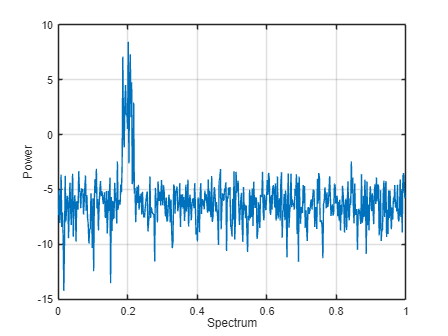

        %%ОЦЕНКА СПМ МЕТОДОМ УЭЛЧА
        
        [pxx,wx] = pwelch(rxSig,[],[],512,[]); %Второе значение - размер окна, третье - прекрытие окон, 
                % четвертое - количество ДПФ преобразований (разделений на них), пятое - указание на какой частоте СПМ
        plot(wx,10*log10(pxx))
        grid
        xlabel('Spectrum')
        ylabel('Power')

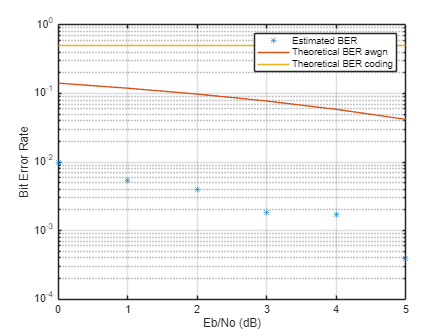

        
        %%ТЕОРЕТИЧЕСКИЕ ЗНАЧЕНИЯ КБО С АБГШ КАНАЛОМ
        
        berTheoryawgn = berawgn(EbNoVec,'qam',M);
        semilogy(EbNoVec,berEst,'*')
        hold on
        semilogy(EbNoVec,berTheoryawgn)
        hold on
        spect = distspec(tPoly,8);
        
        %%ТЕОРЕТИЧЕСКИЕ ЗНАЧЕНИЯ КБО С КОДЕРОМ КАНАЛА:
        
        berTheoryCoded = bercoding(EbNoVec,'conv','hard',codeRate,spect,'qam',M,'nondiff');
        semilogy(EbNoVec,berTheoryCoded)
        grid
        legend('Estimated BER','Theoretical BER awgn','Theoretical BER coding')
        xlabel('Eb/No (dB)')
        ylabel('Bit Error Rate')